%https://se.mathworks.com/help/images/ref/affine2d.transformpointsforward.html
%https://technodocbox.com/3D_Graphics/78643914-Advanced-image-processing-tnm034-optical-music-recognition.html

demoFolder = matlabroot + "/toolbox/images/imdata/";
demoImages = dir(fullfile(demoFolder + "*.*"));
demoImages = string({demoImages.name});
%testImage = im2double(rgb2gray(imread(demoFolder + "cameraman.tif")));
testImage = im2double(imread(demoFolder + "cameraman.tif"));


folder = "Images/";
imageFileNames = dir(fullfile(folder+ "im*c.jpg"));
imageFileNames = string({imageFileNames.name});

preview = [];
allNotes = [];
firstStaffOriginal = [];
firstStaffMask = [];
for i=1:size(imageFileNames, 2)
    disp(imageFileNames(i));
    
    imagePath = folder + imageFileNames(i);
    drawDebug_straightenStaffs = false;
    staffNormalizedWidth = 2048;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Load image and remove background
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    original = imread(imagePath);
    originalgray = im2double(rgb2gray(original)); 
    [notes, region] = removeBackground(originalgray);   
    notes = notes(region(2):region(4), region(1):region(3));

    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Extract alpha of staff lines and create an enclosing
    % mask for each staff.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    lineSearch_angleLimit = 10;
    lineSearch_angleStep = 1;
    lineSearch_minimumLength = round(size(notes,2)*0.4);
    
    % Expand image, otherwise the structuring element might fail near the corners
    paddingWidth = round(lineSearch_minimumLength*0.2);
    paddingHeight = round(paddingWidth*0.2);
    notes = padarray(notes, [paddingHeight, paddingWidth], 1, 'both');
    
    % Attempt to extract the masks
    staffLinesAlpha = getLinesAlphaByAngle(notes, lineSearch_angleLimit, lineSearch_angleStep, lineSearch_minimumLength);
    staffsMask = imclose(staffLinesAlpha, strel('disk', 16, 4));
    staffsMask = (staffsMask > graythresh(staffsMask));

    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Use mask of staffs to detect perspective transform
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [perspective, hasPerspective] = estimatePerspectiveTransform(staffsMask);
    perspectiveInverse = invert(perspective);
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Apply perspective correction to image and alpha
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    notes = 1-imwarp(1-notes, perspectiveInverse, 'cubic');
    staffLinesAlpha = imwarp(staffLinesAlpha, perspectiveInverse, 'cubic');
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Recreate staffsmask post-transform. 
    % Also create a new mask which includes notes hanging
    % outside the staff.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    staffsMask = imclose(staffLinesAlpha, strel('disk', 16, 4));
    staffsMask = (staffsMask > graythresh(staffsMask));
    
    notesMask = (notes < graythresh(notes));
    notesMask = or(notesMask, staffsMask);
    notesMask = bwareaopen(notesMask, size(notes,2));
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Use the mask to remove clutter
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    notes = 1-(1-notes).*notesMask;  

    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Split image into a separate segment for each staff
    % based on the masks.
    %
    % staff (struct)
    %   .image      bitmap containing notes
    %   .staffMask  logical mask which wraps around the five major staff lines
    %   .notesMask  logical mask which also includes the notes hanging outside the staff
    %   .top        top of first staff line
    %   .bottom     bottom of fifth staff line
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [staffs, staffCount] = splitStaffsBasedOnMasks(notes, staffsMask, notesMask);
    
    % Normalize
    for k=1:staffCount
        globalScale = staffNormalizedWidth / size(staffs(k).image, 2);
        
        staffs(k).image     = imresize(staffs(k).image, globalScale, 'bicubic');
        staffs(k).staffMask = imresize(staffs(k).staffMask, globalScale, 'nearest');
        staffs(k).notesMask = imresize(staffs(k).notesMask, globalScale, 'nearest');
        
        staffs(k).top = round(staffs(k).top*globalScale);
        staffs(k).bottom = round(staffs(k).bottom*globalScale);
    end    
    
    
    
    
    
       %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Create splines for first and fifth staff line which will 
    % be used as a base for a bent coordinate system.
    % Creates:
    %   staff.topSpline
    %   staff.bottomSpline
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for k=1:staffCount        
        height = size(staffs(k).image,1);
        width = size(staffs(k).image,2);
        blockWidth = round(height);
        [topPoints, bottomPoints, scatterMask] = getStaffLinesPoints(staffs(k).image, blockWidth);
        
        if isempty(topPoints)
            topPoints = [1, staffs(k).top; width, staffs(k).top];
        end
        
        if isempty(bottomPoints)
            bottomPoints = [1, staffs(k).bottom; width, staffs(k).bottom];
        end
        
        staffs(k).topSpline = spline(topPoints(:,1), topPoints(:,2));
        staffs(k).bottomSpline = spline(bottomPoints(:,1), bottomPoints(:,2));
        
        % Do not straighten image, it is better to query the splines
        %staffs(k).image = straightenImageUsingSplines(staffs(k).image, topSpline);
        
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Draw debug
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if drawDebug_straightenStaffs  
            splineThickness = 1;
            for x=1:width    
                top = round(ppval(x, staffs(k).topSpline));
                bottom = round(ppval(x, staffs(k).bottomSpline));
                
                % Don't allow coordinates outside the image
                topRange = max(1, (top-splineThickness):(top+splineThickness));
                topRange = min(height, topRange);
                bottomRange = max(1, (bottom-splineThickness):(bottom+splineThickness));
                bottomRange = min(height, bottomRange);
    
                scatterMask(topRange, x) = 1;
                scatterMask(bottomRange, x) = 1;
                
                [staffOrigin, staffFifthLine] = getStaffSplineCoordinates(staffs(k), x);
                sinHeight = round((staffFifthLine - staffOrigin)/2);
                sinWidth = size(staffs(k).image,2);
                sinOffset = round(sinHeight*sind(20*360*x/sinWidth) + sinHeight);
                scatterMask(staffOrigin+sinOffset, x) = 1;
                
                stepSize = (staffFifthLine-staffOrigin)/4;
                for step=-2:6
                    yCoord = round(staffOrigin + step*stepSize);
                    if yCoord > 0 && yCoord <= size(staffs(k).image, 1)
                        scatterMask(yCoord, x) = 1;
                    end
                end
            end
            
            imshowpair(scatterMask, staffs(k).image);
            hold on;
            scatter(topPoints(:,1), topPoints(:,2), 'o');
            scatter(bottomPoints(:,1), bottomPoints(:,2), 'o');
            
            % Plot debug text on staff
            for x=1:round(width/8):width
                [staffOrigin, staffFifthLine] = getStaffSplineCoordinates(staffs(k), x);
                stepSize = (staffFifthLine-staffOrigin)/4;
                for step=-2:6
                    text(x, round(staffOrigin + step*stepSize), string(step), 'Color', 'white', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
                end
            end
            
            hold off;
            shg;
            w = waitforbuttonpress;
        end
    end

    allNotes = vertcat(allNotes, staffs.image);      
end

im10c.jpg
im13c.jpg
im1c.jpg
im3c.jpg
im6c.jpg
im8c.jpg
im9c.jpg




%imshowpair(firstStaffOriginal, firstStaffMask, 'montage');

%imshowpair(preview(1).image, preview(2).image, 'montage');

% previewCombined = [];
% previewSize = 2048;
% width = 2;
% height = ceil(size(preview,1)/width);
% for i=1:size(preview,1)
%     previewCombined = cat(3, previewCombined, imresize(makeSquareSize(preview(i).image), [previewSize previewSize], 'bicubic'));
% end
% 
% montage(previewCombined, 'Size', [height width]);


%   %%%%% DUPLICATE OFF GETLINESALPHABYANGLE
%     searchAngle = 1;
%     angleStepSize = 0.5;
%     image = firstStaffOriginal;%staffs(1).image;
%     lineSearchLength = round(size(staffs(1).image,2)*0.25);
%    lines = histeq(image);
%    lines = lines > graythresh(lines);
%    lines = imdilate(lines, strel('rectangle', [3 2]));
%     alpha = ones(size(lines));
%     for angle=-searchAngle:angleStepSize:searchAngle     
%         alpha = alpha .* imclose(lines, strel('line', lineSearchLength, angle));
%     end
%     alpha = 1-alpha;
%     staffs(1).image = image;
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% imshow(alpha);

% temp = firstStaffOriginal;
% lineSearchLength = round(size(staffs(1).image,2)*0.15);
% mask = getLinesAlphaByAngle(temp, 2, 0.5, lineSearchLength, 0);
% accidentalBridgeLength = round(size(staffs(1).image,2)*0.04);
% mask = imerode(mask, strel('line', round(size(staffs(1).image,1)*0.02), 90));
% mask = imopen(mask, strel('line', accidentalBridgeLength, 0));

%imshowpair(firstStaffOriginal, mask, 'montage');
% imshow(mask);

imageSobelledH = edge(firstStaffOriginal, 'sobel', 0.05, 'nothinning', 'horizontal');
imageSobelledV = edge(firstStaffOriginal, 'sobel', 0.01, 'nothinning', 'vertical');
imageSobelledV = imerode(imageSobelledV, strel('line', 10, 90));
imageSobelledV = imclose(imageSobelledV, strel('line', 2, 0));
intersection = and(imageSobelledH, imageSobelledV);
imageS = imageSobelledH;
imageS(intersection == 1) = 0;
%imageS = imclose(imageS, strel('disk', 1, 4));
imageS = imclose(imageS, strel('line', 30, 0));
%imshowpair(imageSobelledV, imageSobelledH);

%imshow(imageS);

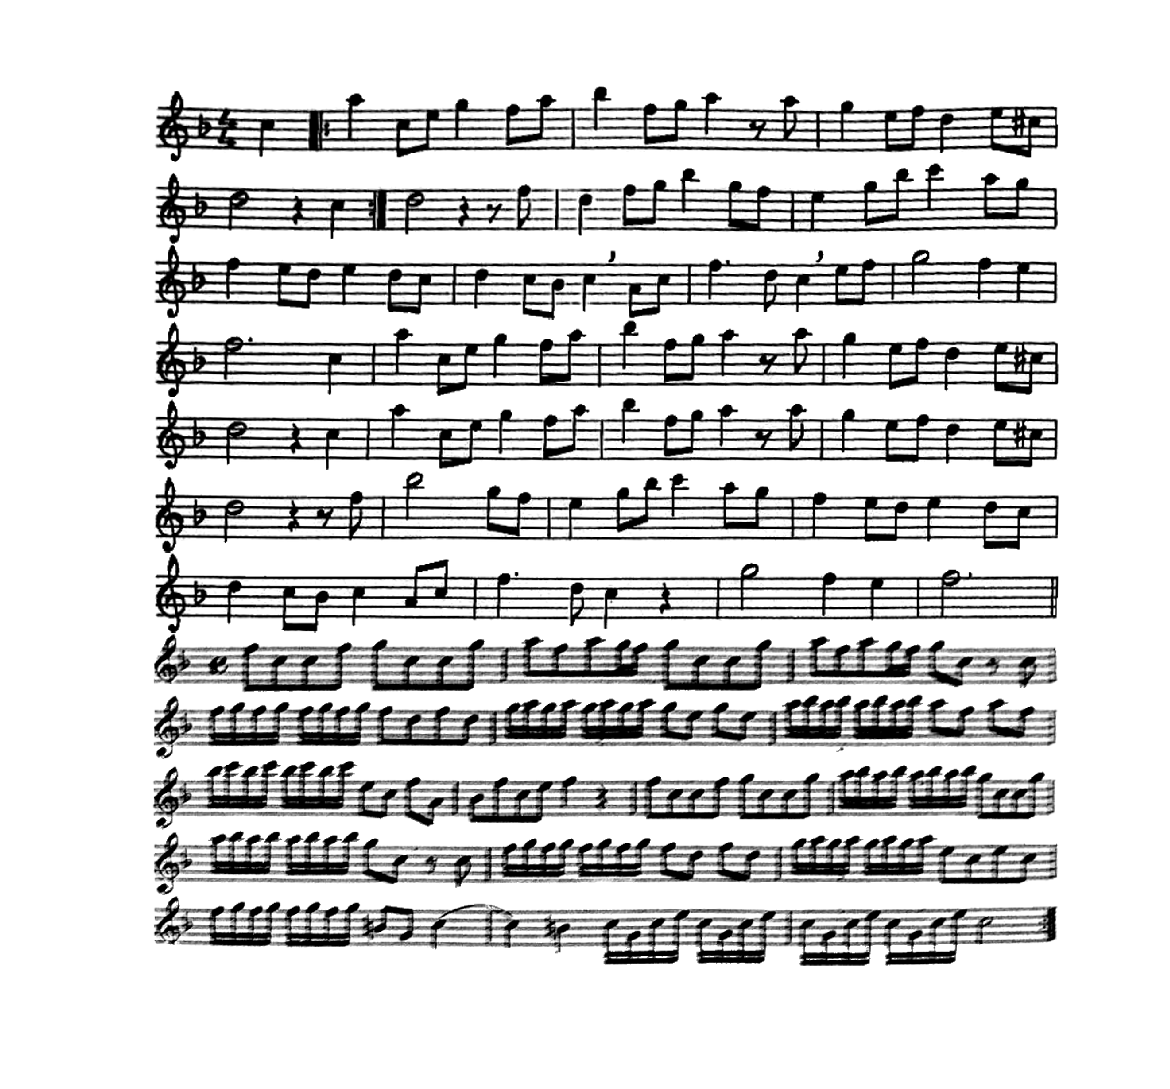


%R = radon(firstStaffOriginal);
%R(R < (max(max(R)) * 0.75)) = 0;

%iminv = iradon(R);
%imshow(iminv);
imshow(allNotes);

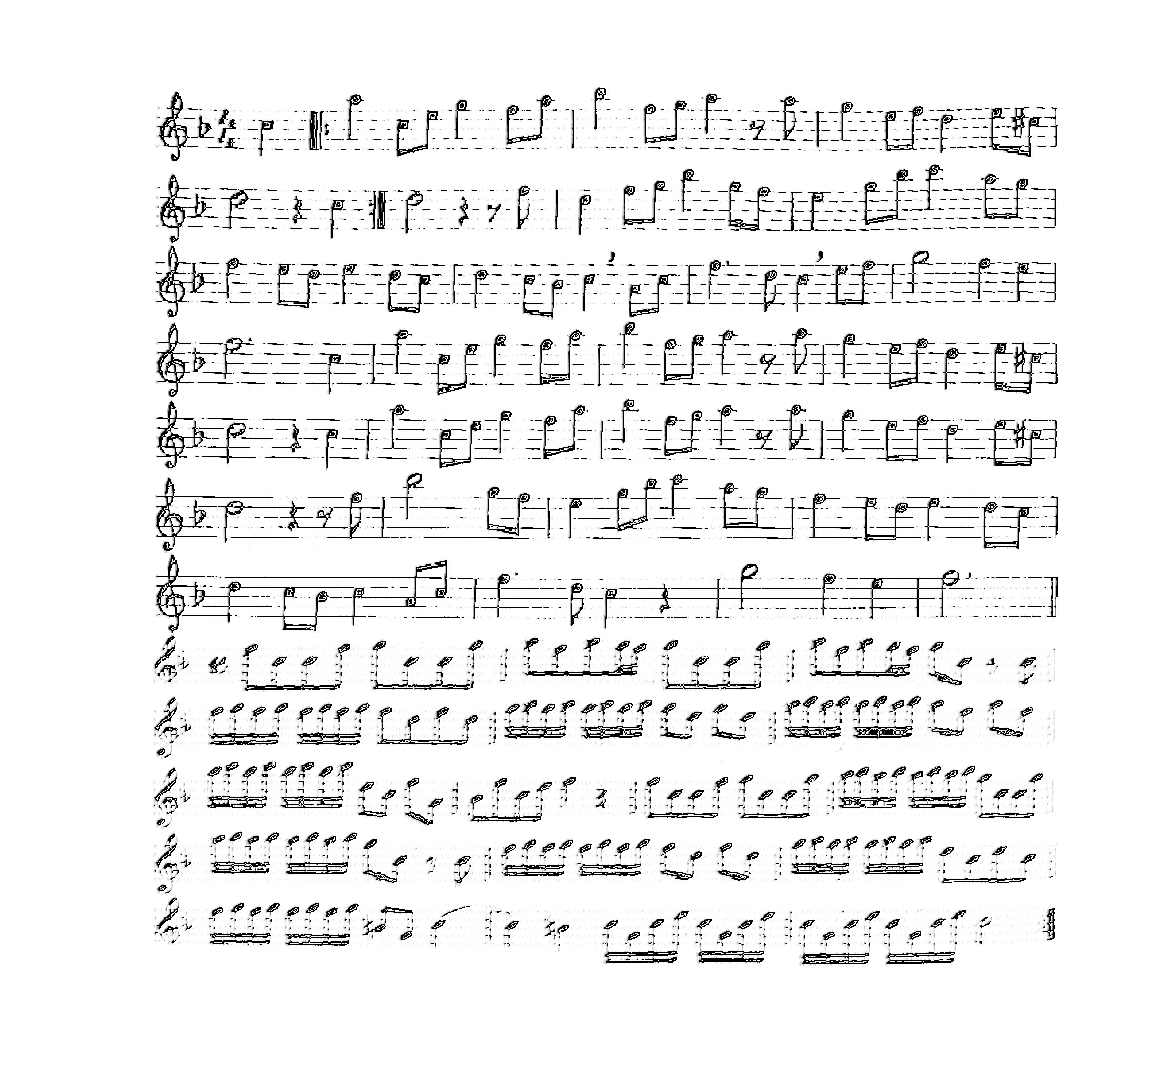


theta = 0:180;%80:0.2:100;
image = 1-allNotes;
image = image > graythresh(image);
[R xp] = radon(image, theta);
maxValue = max(max(R));



R(R < maxValue*0.75) = 0;
R(~imregionalmax(R)) = 0;
%BW = imregionalmax(R);
I1 = iradon(R,theta, 'linear', 'Ram-Lak', 1);
%I1 = imclose(I1, strel('disk', 4, 4));

% imagesc(theta,xp,R);
% title('R_{\theta} (X\prime)');
% xlabel('\theta (degrees)');
% ylabel('X\prime');
% set(gca,'XTick',0:20:180);
% colormap(hot);
% colorbar




%edgeMask = ones(256);
%edgeMask(2:255, 2:255) = 0;
%props = 
%imshow(I1);

%  staffImage = staffs(1).image;
% staffBW = staffImage < graythresh(staffImage);
% width = size(staffBW, 2);
% height = size(staffBW, 1);
% blockSize = 256;
% for x=1:blockSize:width
%     if (x==width); break; end
%     endRegion = min(width, x+blockSize-1);
%     blockWidth = endRegion-x+1;
%     
%     R = radon(staffBW(1:height, x:endRegion));
%     maxValue = max(max(R));
%     R(R < maxValue*0.95) = 0;
%     I1 = iradon(R,0:179, 'linear', 'none', 1, blockWidth) > 0.5;
%     I1 = imclose(I1, strel('disk', 4, 4));
%     
%      heightDiff = size(I1,1)-height+2;
%      heightPadding = round(heightDiff/2);
%     staffBW(1:height, x:endRegion) = I1(heightPadding:(height+heightPadding-1), :);
% end

% height = size(staffImage, 1);
% staffBW = blockproc(staffImage, [height, 256], @radonLineFilter);

staffBW = radonLineFilter(staffs(2).image, 256, 0.5);
staffBW(staffs(2).staffMask == 0) = 0;      % remove residue outside the staff

%imshowpair(staffs(1).image, staffBW);

imshow(allNotes);

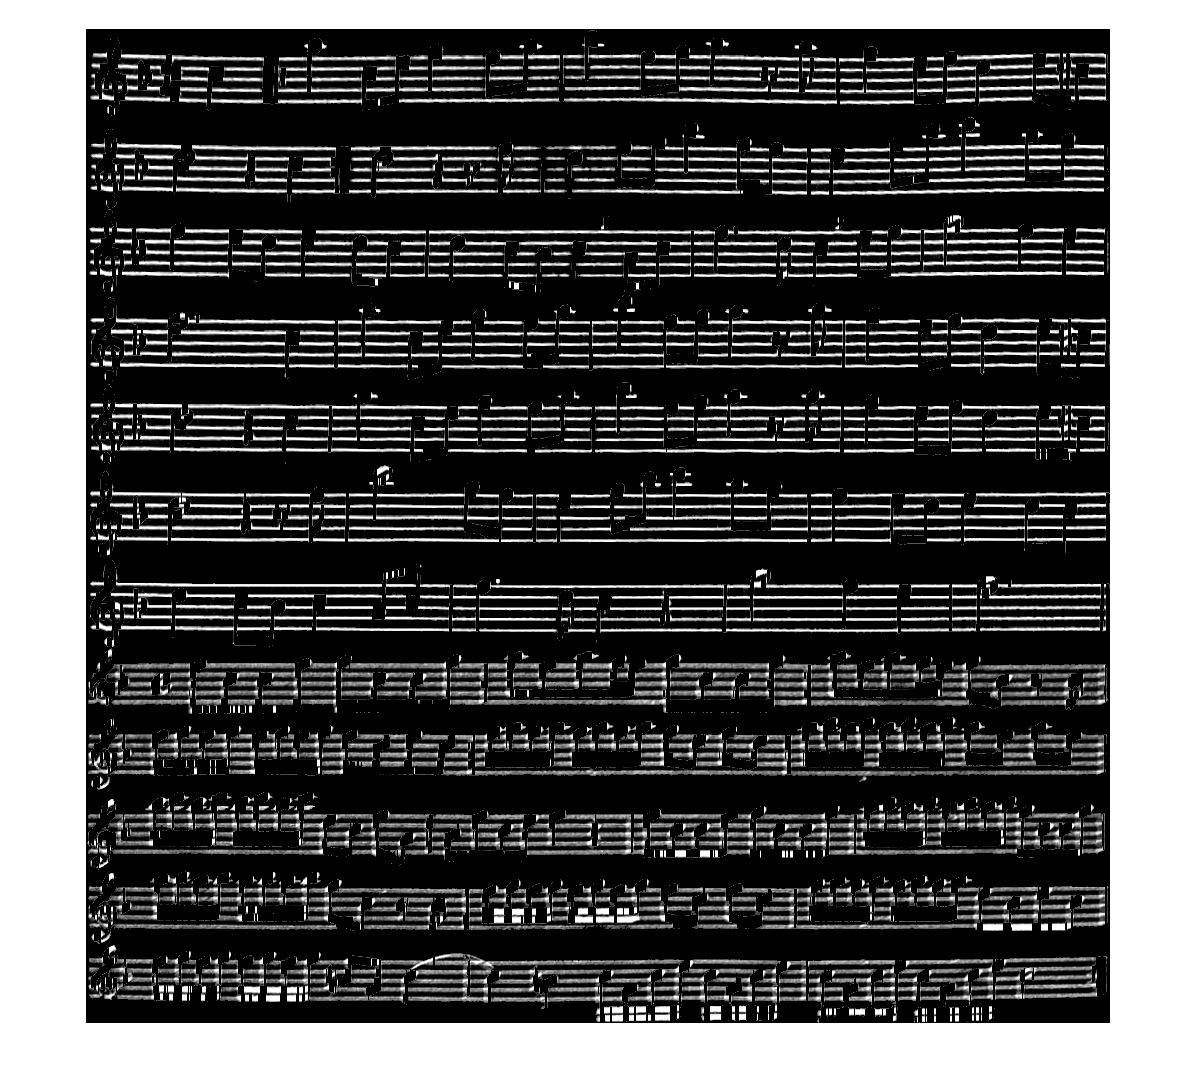

meh = histeq(meh);
meh = imopen(meh < graythresh(meh), strel('line', 15, 90));
meh = (1-meh).*(1-allNotes);
imshow(meh);

% polyfit (least squares) test
if false
    x = linspace(-10, 10, 20);
    slope = 1.5;
    intercept = -1;
    noiseAmplitude = 15;
    y = slope .* x + intercept + noiseAmplitude * rand(1, length(x));
    
    % Plot the training set of data.
    subplot(2, 1, 1);
    plot(x, y, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    grid on;
    xlabel('X');
    ylabel('Y');
    title('Linear Fit');
    
    % Enlarge figure to full screen.
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
    % Give a name to the title bar.
    set(gcf, 'Name', 'Demo by ImageAnalyst', 'NumberTitle', 'Off') 
    
    % Do the regression with polyfit
    linearCoefficients = polyfit(x, y, 1)
    xFit = linspace(-15, 20, 50);
    yFit = polyval(linearCoefficients, xFit);
    hold on;
    plot(xFit, yFit, 'b.-', 'MarkerSize', 15, 'LineWidth', 1);
    legend('Training Set', 'Fit', 'Location', 'Northwest');
    hold off;
    grid off;
    subplot(1,1,1);
end

if false
    I = original;
    [I, background, hullMask] = extractnotesfromphoto(I);
    Iedges = edge(notes, 'sobel', 'nothinning', 'horizontal');
    
    %Ibw = (I < 0.9);
    %Ibw = notesEdges;
    Ibw = Iedges;
    Iskel = Ibw; %bwmorph(Ibw,'thin',inf);
    %%%%radon tranform horizontal
    [R xp] = radon(Ibw);
    [II JJ] = find(R >= (max(max(R)) * 0.75));
    imshow(Ibw); hold on;
    for k = 1 : size(II,1)
        R_i = (JJ(k) - 1) * 1;
        xp_i = xp(II(k));
        x_origin = size(Iskel,2) / 2 + (xp_i) * cos(R_i * pi / 180);
        y_origin = size(Iskel,1) / 2 - (xp_i) * sin(R_i * pi / 180);
        y1 = (y_origin - (1 - x_origin) * tan(((R_i) - 90) * pi / 180));
        ye = (y_origin - (size(Iskel,2) - x_origin) * tan(((R_i) - 90) * pi / 180));
        line([1 size(Iskel,2)], [y1 ye],'color','g');
    end
    
    % lines is a row of [A, B, C] line matrix
    %lines = [pointsToLineEquation(0,0, 5, 5)];
    %points = lineToBorderPoints(lines,size(I));
    %line(points([1,3]),points([2,4]), 'Color', 'Magenta');
    
    p1 = [0,0];
    p2 = [500,500];
    p3 = [200,0];
    p4 = [200,200];
    point = linlinintersect([p1; p2; p3; p4]);
    line(p1, p2, 'Color', 'Red');
    %line(p3, p4, 'Color', 'Blue');
    plot(point, 'Color', 'Magenta');
    hold off;
end

% Polyfit attempt
if false
    % Left edge polyfit
    leftSidePoints = sortrows(leftSidePoints, 2);
    x = leftSidePoints(:,1)';
    y = leftSidePoints(:,2)';
    linearCoefficients = polyfit(y, x, 1);
    f = polyval(linearCoefficients, y);
    figure;
    plot(y, x, y, f);
    
    imshow(imageBW);
    hold on;
    plot(f, y, 'Color', 'red');
    
    
    % Right edge polyfit
    rightSidePoints = sortrows(rightSidePoints, 2);
    x = rightSidePoints(:,1)';
    y = rightSidePoints(:,2)';
    linearCoefficients = polyfit(y, x, 1);
    f = polyval(linearCoefficients, y);
    plot(f, y, 'Color', 'magenta');
    hold off;
end

% Blurry photo fix
if false
    notes = loadimage("images/im13c.jpg");
    notes = extractnotesfromphoto(notes);
    
    %Kaverage = filter2(fspecial('average',3), notes);
    %Kaverage = medfilt2(notes);
    denoised = notes;
    denoised = filter2(fspecial('unsharp'), denoised);
    %denoised = wiener2(denoised,[3 3]);
    imshow(denoised);
    
    %imshow(filterwithfourier(notes, 20));
    
    % sgolay did not help
    %k = 2;
    %windowSize = 5;
    %notesVsmooth = sgolayfilt(notes, k, windowSize, [], 1);
    %notesHsmooth = sgolayfilt(notes, k, windowSize, [], 2);
    %imshowpair(notesVsmooth, notesHsmooth, 'montage');
    
    %h = fspecial('unsharp');
    %I2 = imfilter(notes, h);
    %imshow(I2);
end

% function [result] = plotPerBlock(block)    
%     [originalLines, orthoLines] = houghHorizontalAdjustment(block.data, 2, "nopreprocess");
%     
%     maxAngleOffset = 5.0;
%     maxOffsetX = floor(block.blockSize(2)*0.05);
%     
%     blockx = block.location(2);
%     blocky = block.location(1);
%     
%     filteredLines = [];
%     for i=1:size(originalLines)
%         orgNew = originalLines(i);
%         absAngle = abs(abs(orgNew.theta)-90);
%         if absAngle < maxAngleOffset       
%             orgNew.origin.x = orgNew.origin.x + blockx;
%             orgNew.origin.y = orgNew.origin.y + blocky;
%             orgNew.end.x = orgNew.end.x + blockx;
%             orgNew.end.y = orgNew.end.y + blocky;
%             
%             p1 = orgNew.origin;
%             p2 = orgNew.end;
%             
%             % Only use lines that are close to the block edges
%             if abs(p1.x-blockx) <= maxOffsetX && abs(blockx+block.blockSize(2)-p2.x) <= maxOffsetX
%                 filteredLines = [filteredLines, orgNew];                
%             end
%         end
%     end
%     
%     result = struct;
%     result.lines = filteredLines;
%     result.image = block.data;
% end